# Mid-Semester Data Analysis

Katie Foster

data = readtable("memorycandy.txt");

### Tidy up the data to make it easier to work with.

data= sortrows(data,'CodeName'); %Sort by names (now will be in alphabetical order)
data.CodeName = categorical(data.CodeName); % make categorical to make easier to choose subsets
data.Group = categorical(data.Group); % make categorical to make easier to choose subsets

### Determine how many correct answers each person gave

Make lists of the two answers. 

round1 = {'read','pages','letters','school','study','reading','stories','sheets','pencil','cover'};
round2 = {'house','apple','shoe','book','pencil','flag','rock','train','ocean','glass'};

Loop through all the data and count how many correct. The CorrectInOrder variable marks whether each word in the round1 or round2 list was included in a person's submission (in an order matching the order of round1 or round 2). This results are fairly strict. If someone wrote a singular form of a plural word, this is marked incorrect. You are welcome to update the results to be more lenient (but it's a little annoying to implement). 

The values in NumCorrect sum up how many of the words in round1 or round2 each person correctly recorded.

for i = 1:size(data,1) % loop through each answer
    listofwords = unique(data{i,2:11}); % pull the answers out for each person, and put them into cells to make matlab happy
    if data{i,'List'}== 1
        for w = 1:length(round1) %see if each word in the round1 list is included in the responses
            data.CorrectInOrder(i,w) = max(strcmp(round1(w),listofwords));
        end
        data.NumCorrect(i) = sum(data.CorrectInOrder(i,:));  %add up all that were correct     
        data.List1ContainsBook(i) = sum(contains(listofwords,'book','IgnoreCase',true)) > 0; %Did list 1 responses contain the critical false lure?
        data.List1ContainsPencil(i) = sum(contains(listofwords,'pencil','IgnoreCase',true)) > 0;
        data.List1ContainsHouse(i) = sum(contains(listofwords,'house','IgnoreCase',true)) > 0;
    elseif data{i,"List"} ==2
        for w = 1:length(round2) %see if each word in the round2 list is included in the responses
            data.CorrectInOrder(i,w) = max(strcmp(round2(w),listofwords));
        end
        data.NumCorrect(i) = sum(data.CorrectInOrder(i,:)); %add up all that were correct
    end
end

### Create plots to look primacy and recency.

These plots are just to explore the data and make sure things look reasonable and to see if our findings replicate the results of a famous paper. You won't need these plots for the rest of the analysis, but I wanted to shared with you whether our data showed the primacy (remember the early words) and recency (remember the last word) effects. These effects are shown clearly in Figure 1 of the Roediger and McDermott paper [https://pdfs.semanticscholar.org/9425/1836c4c160574b8887362847795da66c2c81.pdf).](https://pdfs.semanticscholar.org/9425/1836c4c160574b8887362847795da66c2c81.pdf).) Note, they used a moving average to smooth the data.

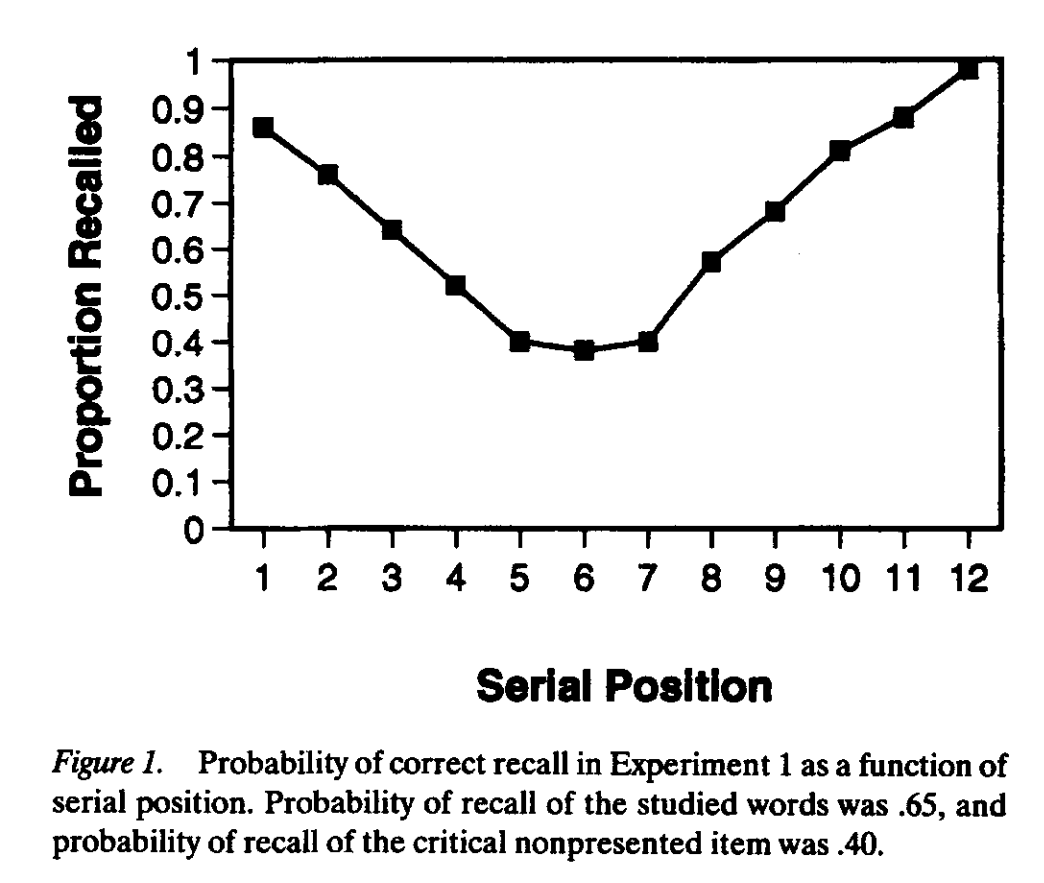

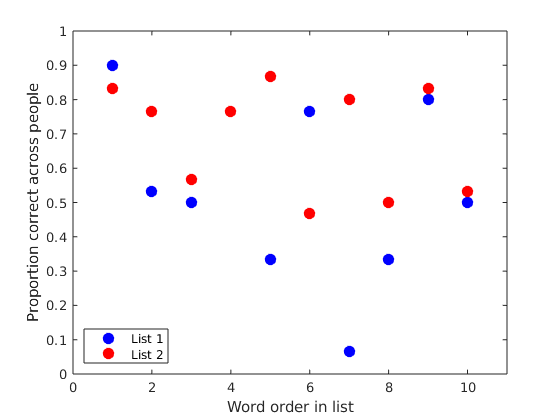

list1order = mean(data.CorrectInOrder(data.List==1,:));
list2order = mean(data.CorrectInOrder(data.List==2,:));

figure;
plot(1:10,list1order,'bo','MarkerSize',8,'MarkerFaceColor',"blue"); hold on;
%plot(1:10,smooth(list1order,3),'b','LineWidth',2); 
plot(1:10, list2order,'ro','MarkerSize',8,'MarkerFaceColor',"red");
axis([0,11, 0, 1]); ylabel('Proportion correct across people'); xlabel('Word order in list'); legend({'List 1','List 2'},'Location',"southwest"); hold off;

The dots represent the data for our two lists. The black line represents a smoothed line to more closely represent the work shown in Figure 1 of the paper. We see the primacy effect, but not the recency effect. We may not expect to see the recency effect, since we waiting quite a while before recalling the lists.

## Answering the Questions

What is the probability that a person falsely recalled “book” in list 1 (writing it down even though it was only on list 2) if we know that person received candy?

% find whether or not list1conains book for those who recieved candy
answers = data.List1ContainsBook(find(data.Group == "Candy"));
% sum and divide by number of entries to find probability
PbGivenC = sum(answers)/length(answers)

PbGivenC = 0.3571

clear answers;

The probability that a person falsely recalled book given that they recieved candy was 0.3571

What is the probability that a random person selected from our class received candy, given that we know they did NOT falsely recall the word “book” in list 1?

% find whether or not recieved candy for those who did not say book
candy = data.Group(find(data.List1ContainsBook == 0));
PcGivenNotb = length(find(candy == "Candy"))/length(candy)

PcGivenNotb = 0.4615

The probability that a random person recieved candy given that they did not falsely recall book is 0.4615

If we added 10 more people, all of whom received candy and none of whom falsely recalled the word “book” in list 1, what would the new probability be for question 2?

FakePcGivenNotb = (length(find(candy == "Candy"))+10)/length(candy)

FakePcGivenNotb = 0.7179

clear candy;

If 10 more people who got candy did not recall book, the new probability would be 0.7179

Did people who received candy perform differently than those that did not receive candy on List 1? (Performance here should be indicated by the number of words correctly recalled.) Please select and conduct an appropriate statistical test, calculate effect size, and create one illustrative well-labeled figure to address each of the following questions. Please interpret your findings in a sentence or two.

candyCorrect = data.NumCorrect(find(data.Group == "Candy"));
noCandyCorrect = data.NumCorrect(find(data.Group == "No Candy"));
% first check overall averages
mean(data.NumCorrect)

ans = 6.2167

mean(candyCorrect)

ans = 6.1071

mean(noCandyCorrect)

ans = 6.3125

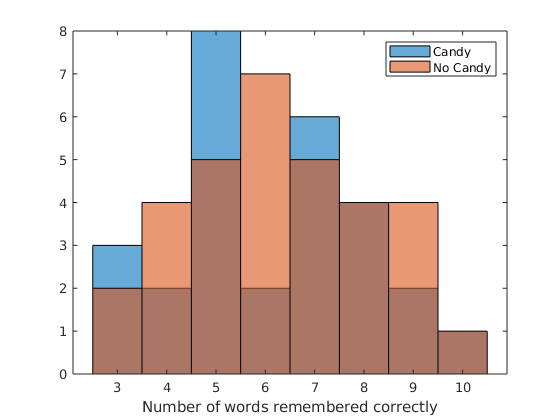

% plot histogram to visually compare
histogram(candyCorrect); hold on;
histogram(noCandyCorrect); hold off;
legend("Candy", "No Candy"); xlabel("Number of words remembered correctly")


% I used an independent samples t test
[h,p,ci,stats] = ttest2(candyCorrect, noCandyCorrect)

h = 0

p = 0.6764

ci =    -1.1852
    0.7745


stats = struct with fields:
    tstat: -0.4195
       df: 58
       sd: 1.8917



% effect size
effect_size = (mean(candyCorrect)-mean(noCandyCorrect))/std(data.NumCorrect)

effect_size = -0.1093

h is 0,  which means that the test fails to reject the null hypothesis. This means that there is no statistical difference between the performance of the group that did recieve candy, compared to the group that did not. This result is supported by the very close averages between the groups, and visually confirmed by the very similar distributions between groups in the histogram

The Roediger and McDermott paper observed that people accuracy recalled 65% of words. Do our results differ from this significantly? 

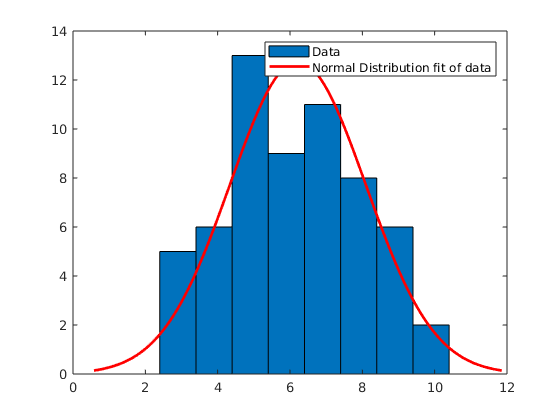

histfit(data.NumCorrect);
legend("Data", "Normal Distribution fit of data");

mean(data.NumCorrect)

ans = 6.2167


% I used a one sample t test, which is used to compare a result to an
% expected value
h = ttest(data.NumCorrect, 6.5)

h = 0


% effect size
effect_size = (6.5 - mean(data.NumCorrect))/std(data.NumCorrect)

effect_size = 0.1508

Since the result of the ttest is 0, we know that the test has failed to reject "the null hypothesis that the data in x comes from a normal distribution with mean m and unknown variance", according to matlab's documentation. That means that our results do not differ significantly from the results from the paper. This conclusion is supported visually by the histogram's normal distribution, which is centered at 6.2, which is close to 6.5. 

Did people perform differently on their recall of the two lists? Please select and conduct an appropriate statistical test, calculate effect size, and create one illustrative well-labeled figure to address each of the following questions. Please interpret your findings in a sentence or two.

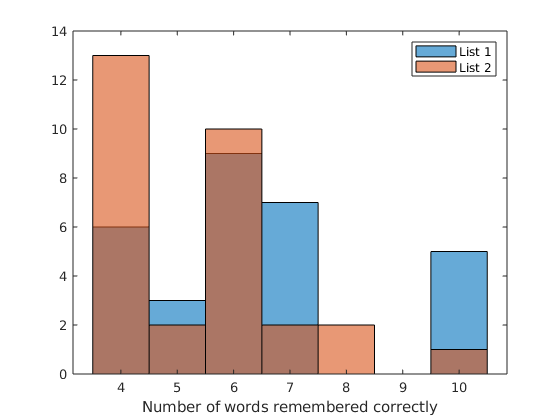

list1correct = data.NumCorrect(find(data.List == 1));
list2correct = data.NumCorrect(find(data.List == 2));

% plot histogram to visually compare
histogram(data.NumCorrect(list1correct)); hold on;
histogram(data.NumCorrect(list2correct)); hold off;
legend("List 1", "List 2"); xlabel("Number of words remembered correctly")


% I used a paired samples t test, which is used to compare repeated
% measures or matched samples, such as two different scores for the same
% person
[h,p,ci,stats] = ttest(list1correct, list2correct)

h = 1

p = 0.0015

ci =    -2.2693
   -0.5973


stats = struct with fields:
    tstat: -3.5065
       df: 29
       sd: 2.2389



% effect size
R = corrcoef(list1correct, list2correct)

R =     1.0000    0.1839
    0.1839    1.0000


Yes, people did perform significanty differently on the two tests, given that the null hypothesis was rejected.